# Characterisation of ultra-short laser pulses

[christophe.peucheret@univ-rennes.fr](mailto:christophe.peucheret@univ-rennes.fr)

## Objectives

The objective of this exercise is to numerically explore some standard characterisation methods for ultra-short laser pulses. 

In particular, the focus will be on 

1. The calculation of autocorrelation traces and definition of their potential and limitations.

2. The calculation of frequency-resolved optical gating (FROG) traces and the implementation of a basic inverse resolution algorithm.   

This assignment is organised as follows.

First some general instructions and a description of key features of Matlab Live scripts will be provided. 

Then the aforementioned methods will be explored. That is where some work is expected from you.

Some Matlab functions are made available to you in the `/functions` folder. You can find the list of these functions and their descriptions in Appendix A.

Since you will be manipulating mathematical representations of optical pulses, it may be useful to have some of their basic properties in mind. Appendix B lists a number of such useful properties, so that you do not need to derive them (again).

## Some instructions and a little bit of preparation

This exercise uses the Live script feature of Matlab, which enables to combine nicely (we hope) formatted text and executable code. You can find more information about Live scripts [here](https://se.mathworks.com/help/matlab/live-scripts-and-functions.html).

This assignment is made of a single Live script file, which is relatively long. You will need to fill in some gaps with your own code and discuss / comment the results directly in this file. Therefore it is not a good idea at this time to try to run the entire script. Some sections have been defined in this script (and you are invited to add your own sections as deemed necessary; see the Live editor menu). You are therefore invited to run each section sequentially.

You can always clear up some selected variables in the Matlab command window or run the Live script from the start again (might become annoying beyond a certain point).

You can also clear the outputs (results of calculations, graphs) generated by the Live script (for instance right click > Clear all output)

You should of course read all the text carefully. 

Questions will be formatted in *italic.*

Your answers, comments, intepretation of the results will be formatted in **bold**. You can use the Live editor menu to format the text, or simply enter your text between double asteriks, i.e. **this will be formatted in bold** will automatically format the text as **this will be formatted in bold**.

Before we take off, let's make a quick Live script test.

*Question: *

*Plot the function* $y = x^2$ for $x\in \left[-5,5\right]$

You can insert some Matlab code (Insert > Code)

x = linspace(-5,5,100);
y = x.^2;
figure('Name','the figure I am asked to plot')
plot(x,y,'b-')
xlabel('x')
ylabel('y')

You can now execute the code block.

This will execute the code in the entire section. In our case there is only one code block in the section. You can actually see the section delimiters as blue horizontal lines in the Live script and blue striping in the left margin.

If you now Run the current section, the graph will appear in the right panel.

You can also make the results appear inline (Right margin > Show outputs inline), which will be easier at some points to make them appear sequentially with respect to your code snippets and comments.

You can now clear the output of this section, which, let's admit it, is of little interest: Right click > Clear all ouptut or Right click > Clear output 

You can also define Matlab functions in a Live script. However, a requirement is that these functions are defined at the very end of the script. Therefore a special section entitled Your functions has been created for you to write as many functions as you like. Guess where it is located?

You might need to help Matlab find the path to your simulation folder. This can be done by indicating the path to the folder where you have extracted the archive in the line below, uncommenting it and running the current section.

% addpath(genpath('C:\path\to\lub_simulations'));

Ready to fly?

We just make sure we start with a clean workspace

% ------------------------------------------------------------------------- 
% Clean up
% ------------------------------------------------------------------------- 
clear all
close all

As usual in the study of signals, we need to properly define time and frequency axes. 

For the sake of this simulation exercise, it does not really matter whether the pulse duration is 10 fs, 100 fs or 1 ps... Consequenty, the time interval between samples $\Delta t$ is arbitrarily chosen to be equal to 1. This is equivalent to expressing all durations as multiples of $\Delta t$, i.e. we normalise the values of the time axis by $\Delta t$.  

Obviously the sampling frequency  $f_s = 1/\Delta t$ will be equal to 1.

Note that the time axis is defined symmetrically around $t = 0$.

% -------------------------------------------------------------------------
% Global simulation parameters
% -------------------------------------------------------------------------
dt = 1;
fs = 1/dt;
nsamples = 2^8;
df = 1/dt/nsamples;

time_array = (-nsamples/2:nsamples/2 - 1)*dt;
frequency_array = (-nsamples/2:nsamples/2 - 1)*df;

You can now execute this section before moving to the next. The time and frequency variables should appear in your Matlab workspace.

You will keep these values of global parameters throughout the simulations.

## Limits of detection of short-pulses with bandwidth-limited electronics

A common method to measure pulses and waveforms is to use an oscilloscope. If the pulse is optical, then a photodetector could be first employed to convert the signal from the optical to the electrical domain. This is a standard characterisation method for numerous types of optical signals, such as the ones employed in optical communication systems.

One can distinguish real-time and equivalent-time sampling oscilloscopes, the latter exploiting the periodic nature of test signals in order to allow the use of significantly reduced sampling frequencies. Pulsed signals emitted by mode-locked lasers being inherently periodic, they comply with this requirement. Besides their sampling frequencies, high-speed optical oscilloscopes are also limited by their bandwidth, which is of the order of 100 GHz for state-of-the-art equipment. High-speed photodiodes have a bandwidth of the same order of magnitude. 

We can make a quick back-of-an-envelope calculation to better understand the difficulty associated with this otherwise straightforward pulse characterisation method.

Let's imagine we attempt to characterise pulses with a full-width at half-maximum duration of 100 fs. We can assume the pulses have a Gaussian shape and are unchirped.

*What is the spectral width of such pulses?*

% YOUR CODE HERE

*What minimum bandwidth would be required for proper characterisation using a photodiode followed by an oscilloscope? Conclude.* [Remember to type your answers in **bold**.]

And before you answer, just a hint: keep in mind the relation between optical bandwidth and electrical bandwidth.

The effect of the gap between pulse spectral width and the bandwidth of standard optoelectronic and electronic components is illustrated in Fig. 1.

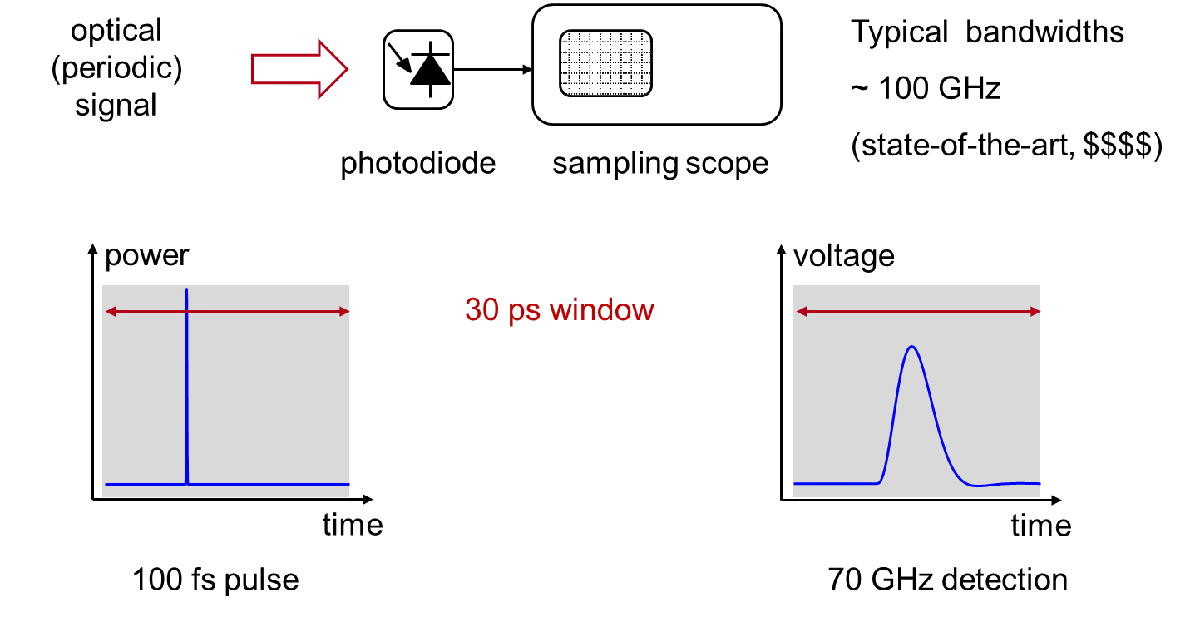

Figure 1  Limitations of the characterisation of short pulses using standard electronic devices. 

The bandwidth limitation of the photodiode and the sampling oscilloscope results in a measured pulse duration that is significantly larger than the duration of the actual pulse. Some pulse distortion is also introduced by the low-pass filtering process associated to the bandwidth limitation. Clearly, this does not qualify as a measurement method.

Furthermore. such a method based on direct-detection would not allow the characterisation of the phase of the pulses. Retrieving the phase properties of short laser pulses is, however, as important as determining their power profile.

We are thus bound to invent short-pulse characterisation methods that can accommodate low-speed electronics.

Such techniques exist, although also potentially suffering from some kind of limitations. Typical methods include: 

- intensity autocorrelation,

- frequency-resolved optical gating (FROG) and related techniques.

which are the objects of the next two sections.

## Intensity autocorrelation

### Principle of autocorrelation measurement

A typical autocorrelation set-up is schematically represented in Fig. 2. The idea is to make two copies of the pulse to be characterised interact in a medium presenting a second-order nonlinearity. One copy will be delayed with respect to the other by a value $\tau$  that is set thanks to a variable delay line.

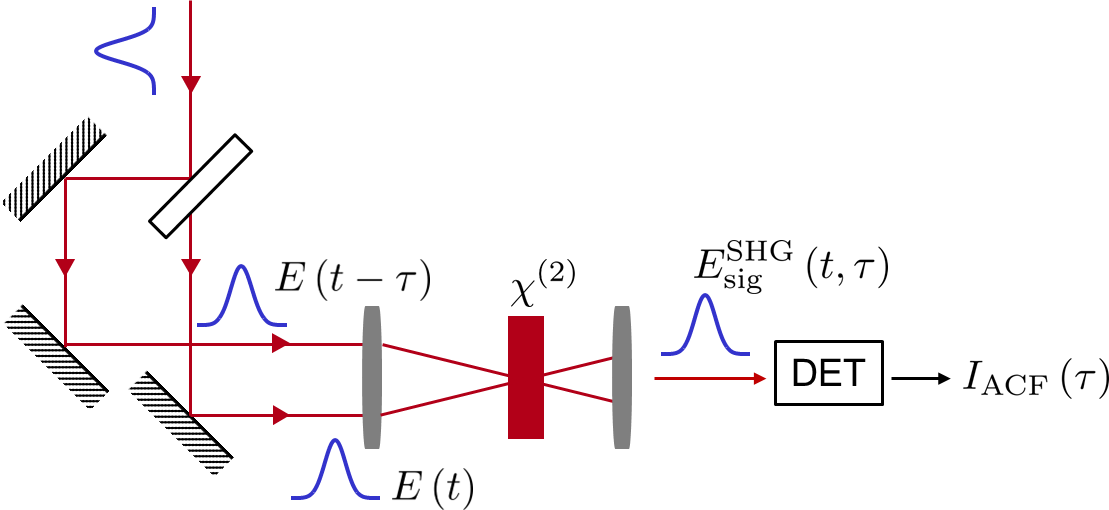

Figure 2 Principle of an intensity autocorrelation set-up exploiting second-harmonic generation in a second-order nonlinear medium. 

Due to the nonlinear interaction between the two copies of the pulses in the nonlinear crystal, a second-harmonic generation (SHG) signal whose field is


$$E_\mathrm{sig}^\mathrm{SHG}\left(t,\tau\right) \propto E\left(t\right) E\left(t- \tau\right)$$


is created. The intensity of the SHG field is therefore


$$I_\mathrm{sig}^\mathrm{SHG}\left(t\right) \propto I\left(t\right)I\left(t-\tau\right).$$


The SHG signal is then fed into a photodiode. Due to the limited bandwidth of the photodiode, the generated photocurrent is unable to follow the instantaneous variations of $I_\mathrm{sig}^\mathrm{SHG}\left(t,\tau\right)$. The action of the - slow - photodiode is, however, to integrate the SHG intensity, resulting in


$$I_\mathrm{ACF}\left(\tau\right) = \int_{-\infty}^{+\infty} I\left(t\right) I\left(t - \tau\right) \; \mathrm{d}t,$$


i.e. the photocurrent is the autocorrelation of the field intensity. Note that in writing this last relation, we have taken the liberty to replace the 'proportional to' sign by the 'equal' sign through proper normalisation of the fields and current. In fact, we are only interested here in the pulse shape and we can therefore work with normalised quantities. The average power can be determined by other characterisation means. 

Obviously, the properties of the autocorrelation function of the *intensity* of the field already tell us a lot about the expected shortcomings of the method. We will verify some of those through numerical simulations.

In practice, on can continuously change the delay $\tau$ (for instance using a motorised translation stage) and directly measure the photocurrent $I_\mathrm{ACF}\left(\tau\right)$. Note that physical processes other than second-harmonic generation can also be exploited.

Next, you will calculate the autocorrelation traces of various pulse shapes and discuss the results.

### Intensity autocorrelation of various pulse shapes

In Matlab, the autocorrelation can be directly calculated from the pulse intensity as follows

where `tfield` is a time domain field.

#### Gaussian pulse

Consider an unchirped Gaussian pulse of FWHM (normalised with respect to the sampling step $\Delta t$) $t_\mathrm{FWHM}= 20$. 

 *Generate the pulse*

We suggest that you give a unique identifier to the field (for instance `tfield_gauss_unchirped`) and all subsequently calculated quantities (for instance the frequency domain field, `ffield_gauss_unchirped`, etc) since you will reuse these fields later on in the assignment. Be systematic in this use of suffixes. 

% YOUR CODE HERE

*Represent the pulse (power) in the time domain* 

% YOUR CODE HERE

*Verify that the generated pulse has the correct FWHM* 

% YOUR CODE HERE

*Calculate the pulse spectrum*

% YOUR CODE HERE

*Represent the pulse spectrum (power)*

% YOUR CODE HERE

*Determine the spectral width (FWHM)*

% YOUR CODE HERE

*Calculate the time-bandwidth product*

% YOUR CODE HERE

*And verify that this value is in agreement with the theoretical value*

% YOUR CODE HERE

You now have a first pulse to play with. You will reproduce some of the calculations above for other pulses. You can copy and paste some of the lines of code above (in a single code block from now on) for other pulses, and simply adapt the suffix of the names of the variables.

*Calculate and represent the autocorrelation trace of the unchirped Gaussian pulse*

% YOUR CODE HERE

*Extract the FWHM of the autocorrelation trace*

% YOUR CODE HERE

*Find a relation between the FWHM of an unchirped Gaussin pulse and the FWHM of its autocorrelation trace*

% YOUR CODE HERE

*You may not be the first one who tries to relate the FWHM of a pulse to the FWHM of its autocorrelation trace. How does your relation compare with what you can find in the literature?*

#### Pulse with cubic spectral phase

You will now consider a pulse with a cubic spectral phase. Such a pulse can be generated in the frequency domain, then converted to the time domain. You will consider a pulse whose spectral width is the same as that of the unchirped Gaussian pulse you studied above.

*Generate the pulse and plot its power in the time domain.*

% YOUR CODE HERE

*What is the effect of changing the sign of the cubic spectral phase term?*

% YOUR CODE HERE

*Calculate and plot the autocorrelation of the pulse, for both signs of cubic phase.*

% YOUR CODE HERE

*Comment the results*

#### Hyperbolic secant pulse

*Repeat the calculations made for an unchirped Gaussian pulse, but this time for an unchirped hyperbolic secant pulse*

% YOUR CODE HERE
% JUST COPY & PASTE AND ADAPT
% REMEMBER TO ADAPT THE NAMES OF THE VARIABLES

*Find a relation between the FWHM of an unchirped hyperblic secant pulse and the FWHM of its autocorrelation trace and compare with what you can find in the literature*

% YOUR CODE HERE

#### What can we learn from the intensity autocorrelation?

You must have observed through your simulation results that there is a direct mapping between the pulse duration and the duration of its intensity autocorrelation trace (both taken as FWHM).

Furthermore, this mapping is dependent on the actual pulse shape.

*Then what can we use the autocorrelation for?*

*What happens when the pulse is chirped? Would its autocorrelation trace be modified compared to that of an unchirped pulse?*

*What about the phase characterisation then?*

*Imagine that we know that the pulse is Gaussian but we do not know its duration nor whether it is chirped. Can we then exploit the autocorrelation together with another simple measurement to conclude?*

Obviously, while the intensity autocorrelation measurement can provide some information about the pulse, it does not generally allow a full characterisation of the field in amplitude and phase.

We thus need to turn to another method that will add the little extra information that will enable full field characterisation.

## Frequency-resolved optical gating (FROG)

### The FROG trace

In order to solve some of the limitations of the characterisation of short pules based on autocorrelation, a method known as frequency-resolved optical gating (FROG) was introduced in the early 1990's [1]. Interestingly, the setup, represented in Fig. 3 for a variant of the method known as SHG-FROG, is nearly identical to that of an intensity autocorrelator, apart from the fact that the detector is replaced by a spectrometer.

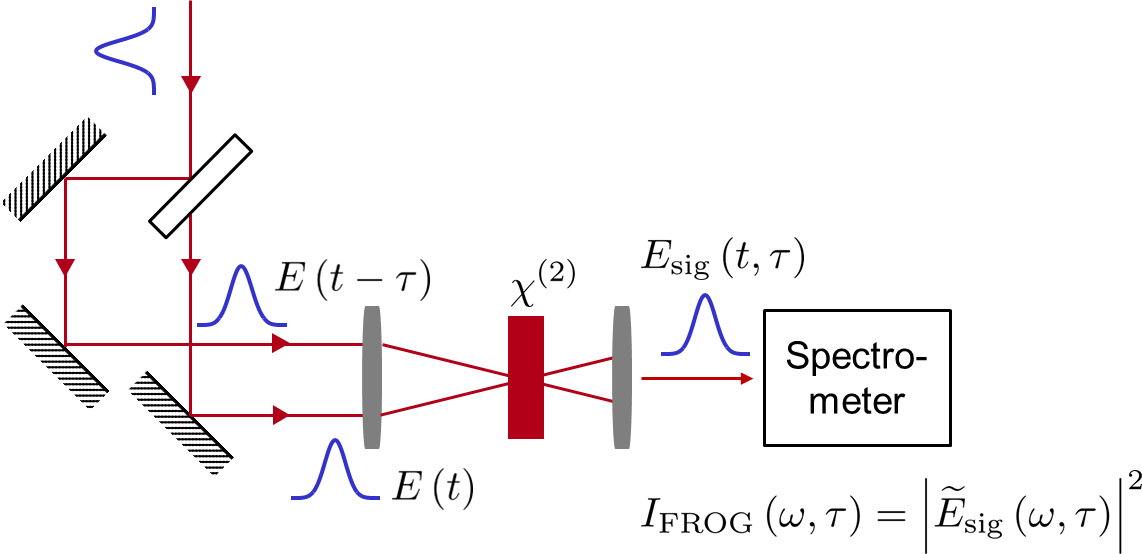

Figure 3 SHG-FROG set-up.

The measured quantity, known as FROG trace and noted $I_\mathrm{FROG}\left(\omega,\tau\right)$, is therefore a frequency-resolved autocorrelation trace


$$I_\mathrm{FROG}\left(\omega,\tau\right) = \left|\int_{-\infty}^{+\infty}E_\mathrm{sig}\left(t,\tau\right) \; e^{-j\omega t}\;\mathrm{d}t\right|^2,$$


were, in the case of SHG-FROG


$$E_\mathrm{sig}\left(t,\tau\right) = E\left(t\right)E\left(t - \tau\right).$$


In practice, it means that, for each value of the delay $\tau$ in the autocorrelation set-up, a spectrum is measured by the spectrometer, leading to a two-dimensional data $I_\mathrm{FROG}\left(\omega,\tau\right)$ known as FROG trace. We shall see that it is actually possible to retrieve a complete characterisation of the pulse, in amplitude and phase, from the FROG trace.

It happens that other nonlinear effects than SHG / other beam geometries can be exploited to generate a FROG trace [2]. In another implementation of the method known as polarisation-gating (PG) FROG, the signal whose spectrum is measured is


$$E_\mathrm{sig}\left(t,\tau\right)= E\left(t\right)\left|E\left(t-\tau\right)\right|^2.$$


We will not look into the optical implementation details in this exercise.  More generally, one can write the signal whose spectrum is measured


$$E_\mathrm{sig}\left(t,\tau\right) = E\left(t\right) g\left(t-\tau\right),$$


where $g\left(t\right)$ is a gate function that is the field to characterise itself in the case of SHG-FROG or its intensity in PG-FROG.

A review of the FROG method can be found in [3].

In what follows, you will first calculate the FROG traces of some of the pulses you had earlier tried to characterise using their intensity autocorrelation and observe how the pulse attributes (pulse shape, frequency chirp) affect the FROG traces. You will be concerned with both PG-FROG and SHG-FROG geometries. In a second part, you will examine whether it is possible to retrieve the complete pulse field $E\left(t\right)$ from its FROG trace $I_\mathrm{FROG}\left(\omega,\tau\right)$ .

### From pulses to FROG traces

You are provided with a simple Matlab function enabling to calculate FROG traces from pulse field vectors expressed in the time domain

The function has as inputs the complex field to characterise $E\left(t\right)$ and the gate function $g\left(t\right)$ and returns both $\widetilde{E}_\mathrm{sig}\left(\omega,\tau\right)$ and the FROG trace $I_\mathrm{FROG}\left(\omega,\tau\right) = \left|\widetilde{E}_\mathrm{sig}\left(\omega,\tau\right)\right|^2$.

The motivation to return the field on top of the FROG trace is to allow the same function to be used in the pulse retrieval algorithm that will be presented later on.

The FROG trace returned by the function is normalised so that its maximum value is equal to 1.

#### Unchirped Gaussian pulse

*Calculate and visualise the PG-FROG trace obtained for the unchirped Gaussian pulse considered previously*

For plotting the FROG trace, we recommend using the Matlab `pcolor `function.

% YOUR CODE HERE

*Calculate and visualise the SHG-FROG trace for the same unchirped Gaussian pulse*

% YOUR CODE HERE

#### Linearly-chirped Gaussian pulse

You will now consider a linearly-chirped Gaussian pulse with normalised chirp rate $b = 0.01$. The pulse normalised FWHM will be kept to $t_\mathrm{FWHM} = 20$. 

Linear-chirp implies a quadratic temporal dependence of the phase according to

$\phi\left(t\right) = - b t^2$.

Remember to name the generated field in a meaningful way. It will be used later on in the assignment. For instance it could be something like `tfield_gauss_b001 `or anything you find convenient. This applies to all generated fields.

*Calculate and plot its PG and SHG FROG traces*

% YOUR CODE HERE

*Repeat the FROG trace calculations (both PG and SHG), this time with a negative linear chirp parameter,* $b = -0.01$

% YOUR CODE HERE

*Comment your findings*

#### Gaussian pulse with quadratic temporal chirp

*Calculate the FROG traces for a Gaussian pulse with FWHM *$t_\mathrm{FWHM}=20$*, no linear and self-phase modulation chirp, and normalised quadratic chirp parameter of* $c = 0.0005$

Quadratic chirp implies a cubic temporal dependence of the phase according to

$\phi\left(t\right) = - c t^3$.

% YOUR CODE HERE

*What happens when the sign of the quadratic temporal chirp parameter is changed?*

% YOUR CODE HERE

#### Gaussian pulse with SPM chirp

We can also consider pulses having a temporal phase similar to what would be aquired due to self-phase modulation (SPM) when propagating in a third-order nonlinear medium


$$\phi\left(t\right) = q \left|E\left(t\right)\right|^2,$$


where $q$ is a SPM chirp parameter.

*Calculate and plot both PG and SHG FROG traces for a Gaussian pulse of the same duration as before, but presenting an SPM chirp parameter of *$q=2$* (and no linear and quadratic chirp).*

% YOUR CODE HERE

*Comment*

#### Pulse with cubic spectral phase

*Calculate and plot both PG and SHG FROG traces for the pulse presenting cubic spectral phase whose autocorrelation has been calculated earlier.*

% YOUR CODE HERE

*Do you see any influence of the sign of the cubic spectral phase term?*

### The inverse problem

You should have now seen how varying the pulse properties, especially its phase, which is the tricky part to characterise, affect the FROG trace. You should have observed quite different FROG traces depending on whether the chirp was linear, quadratic, or due to SPM.

Once this observation is made, a natural question is whether it is possible to retrieve the pulse complex field (i.e. amplitude and phase) from the knowledge of its FROG trace.

This is known as an *inverse problem*.

Of course, solving the inverse problem requires that there cannot be two different complex pulses resulting in the same FROG trace.

A FROG trace is a special case of a quantity known more generally as a *spectrogram*.  Spectrograms are encountered in many scientific fields and the inverse problem, known as *phase retrieval* has been very much investigated.

There are, in the most general case, no solution to the inverse problem. However, by introducing some constraints, for instance based on the knowledge of some properties of the pulse, the inverse problem can sometimes be solved. In many cases, a mathematical proof of the resolution of the inverse problem cannot be found, but experience shows that its resolution works in most cases of practical interest, which can be good enough.

Luckily, in the case of the characterisation of short optical pulses using a FROG apparatus, some algorithms enabling the retrieval of the pulse field from the FROG traces have been identified. One such algorithm is known as the *iterative Fourier transform algorithm*. 

The algorithm is represented schematically in Fig.4 and described below.

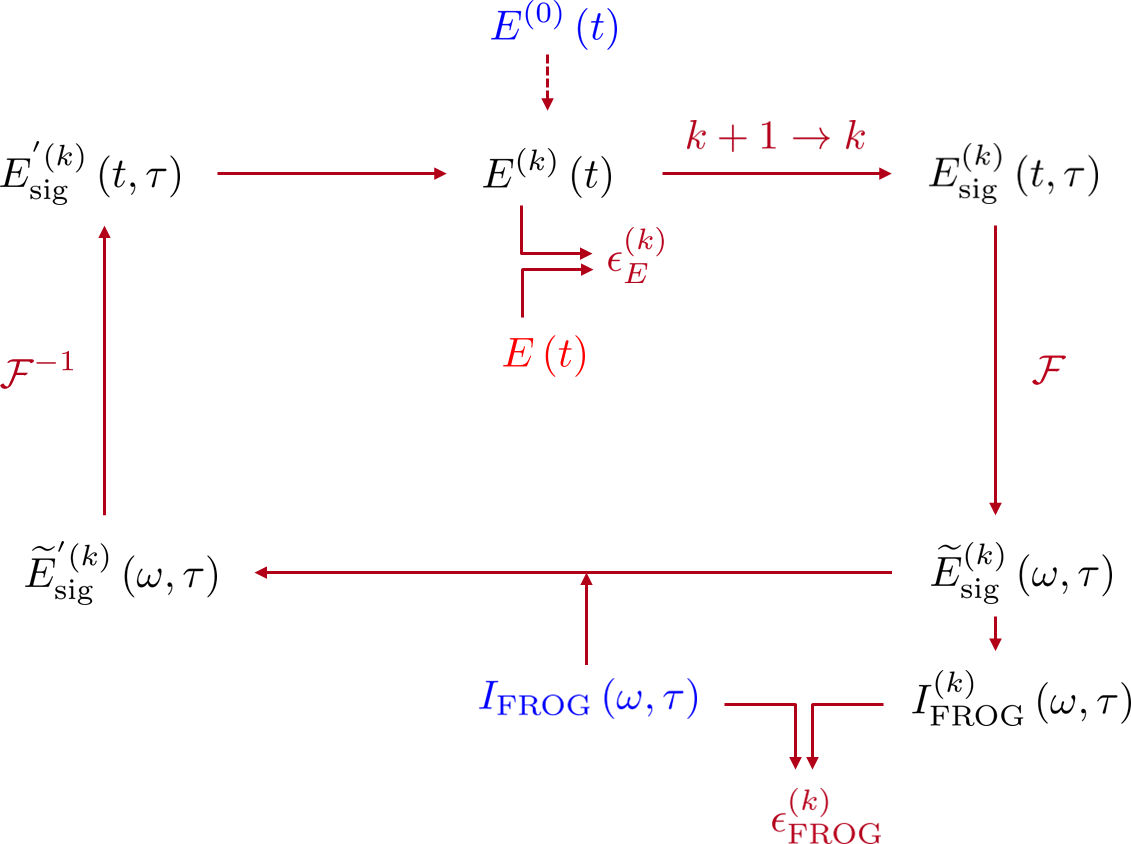

Figure 4 Principle of iterative Fourier transform algorithm for the recovery of the pulse field $E\left(t\right)$ from the FROG trace $I_\mathrm{FROG}\left(\omega,\tau\right)$. 

The goal of the algorithm is to retrieve the pulse complex field $E\left(t\right)$ from the FROG trace $I_\mathrm{FROG}\left(\omega,\tau\right)$. Hopefully we know the beam geometry used in the apparatus, i.e. we know the dependence between $E_\mathrm{sig}\left(t,\tau\right)$ and $E\left(t\right)$, for instance in the case of PG-FROG (reproduced here for convenience)

$E_\mathrm{sig}\left(t,\tau\right)= E\left(r\right)\left|E\left(t - \tau\right)\right|^2$.

The algorithm operates as follows.

We start with an initial "guess" $E^{\left(0\right)}\left(t\right)$ for the field. This can be a pulse shape based on some extra knowledge of the pulse we may have or a constant field. In most cases, some noise field will work surprisingly well. 

We can then calculate $E_\mathrm{sig}^{\left(k\right)}\left(t,\tau\right)$  (where $k$ is an iteration index, i.e. here $k=1$) based on the knowledge of the physical implementation of the FROG apparatus, i.e., for PG-FROG


$$E_\mathrm{sig}^{\left(k\right)}\left(t,\tau\right) = E^{\left(k-1\right)}\left(t\right)\left|E^{\left(k-1\right)}\left(t -\tau\right)\right|^2$$


By Fourier transformation with respect to the first variable (time), we obtain $\widetilde{E}_\mathrm{sig}^{\left(k\right)}\left(\omega,\tau\right)$ . Note that, since the FROG trace is defined as $\left|\widetilde{E}_\mathrm{sig}\left(\omega,\tau\right)\right|^2$ , this operation is exactly the same as what we had done in simulations to calculate the FROG trace from the field using the provided Matlab function `[ifrog,esigw] = frog_trace(sig,gate)`. Therefore this function can be directly used in the pulse retrieval algorithm (which was the reason why `esigw` is also returned by the function...)

Now, we introduce our knowledge of the "measured" FROG trace $I_\mathrm{FROG}\left(\omega,\tau\right)$. 


$$\widetilde{E}_\mathrm{sig}^{'\left(k\right)}\left(\omega,\tau\right) = \frac{\widetilde{E}^{\left(k\right)}\left(\omega,\tau\right)}{\left|\widetilde{E}_\mathrm{sig}^{\left(k\right)}\left(\omega,\tau\right)\right|}\sqrt{I_\mathrm{FROG}\left(\omega,\tau\right)},$$


i.e. we normalise $\widetilde{E}^{\left(k\right)}\left(\omega,\tau\right)$ so that its intensity is equal to the measured FROG trace. By inverse Fourier transform with respect to the first variable, $E_\mathrm{sig}^{'\left(k\right)}\left(t,\tau\right)$ can be calculated, from which a new estimate of the field is made by integration along the delay variable


$$E^{\left(k\right)}\left(t\right) = \int_{-\infty}^{+\infty} E_\mathrm{sig}^{'\left(k\right)}\left(t,\tau\right)\;\mathrm{d}\tau.$$


To justify this last equation, we can observe that if $E_\mathrm{sig}\left(t,\tau\right)$ is calculated from the actual field $E\left(t\right)$, then $\int E_\mathrm{sig}\left(t,\tau\right)\;\mathrm{d}\tau$ returns $E\left(t\right)$ assuming a proper normalisation of the field.

We then iterate over $k$ until a proper convergence is obtained.

Note that since we calculate $\widetilde{E}_\mathrm{sig}^{\left(k\right)}\left(\omega,\tau\right)$ at each iteration, we have access to the FROG trace $I_\mathrm{FROG}^{\left(k\right)}\left(\omega,\tau\right)$ that would be obtained from the estimate $E^{\left(k\right)}\left(t\right)$ of the field. If this estimate has converged towards the actual field $E\left(t\right)$, then the calculated $I_\mathrm{FROG}^{\left(k\right)}\left(\omega,\tau\right)$ should converge towards the measured $I_\mathrm{FROG}\left(\omega,\tau\right)$. We thus have a mean to check the convergence of the algorithm through the calculation of the roor mean-square (rms) error


$$\epsilon_\mathrm{FROG}^{\left(k\right)} =\left[\frac{1}{N^2}\sum_{i=1}^N\sum_{j=1}^N \left|I_\mathrm{FROG}^{\left(k\right)}\left(\omega_i,\tau_j\right) - I_\mathrm{FROG}\left(\omega_i,\tau_j\right)\right|^2\right]^{\frac{1}{2}}.$$


In the present case of attempt of retrieval of a pulse from a numerically calculated FROG trace (i.e. we know the actual pulse field $E\left(t\right))$, we can furthermore calculate a pulse root mean square error


$$\epsilon_E^{\left(k\right)}= \left[\frac{1}{N} \sum_{i = 1}^N \left|E^{\left(k\right)}\left(t_i\right) - E\left(t_i\right)\right|^2\right]^{\frac{1}{2}}.$$


Obviously this quantity is not accessible when one attempts to retrieve an unknown field from a measured FROG trace. 

Note that for the calculation of the mean square errors above (and for the convergence of the algorithm as a whole), it is necessary to properly normalise and retime the fields, as well as to normalise the FROG trace.

The Matlab function

will be used to retime the pulses so that their maximum amplitude occurs at $t=0$ and normalise this amplitude to $E\left(0\right)= 1$ (note that $E\left(t\right)$ is complex, therefore a normalisation in amplitude and phase is actually performed). 

This algorithm will work surprisingly well for "well-behaved" pulse fields. It may nevertheless fail for "complex" pulse shapes, for instance exhibiting oscillatory structures. More robust algorithms have been proposed (for instance the method of so-called generalised projections [4]) but the basic algorithm described in detail above should play the trick in this exercise.

Some practical aspect of implementation are discussed in [2,5]

And now, guess what? Yes, you will be implementing the basic FROG retrieval algorithm. 

You will will write a Matlab function implementing the FROG algorithm for the PG-FROG method.This function will be  written in the Your functions section of this Live script. A detailled template of the function is provided. You will then test it on FROG traces / pulse fields of increased complexity.

Before you implement the function, a few Matlab tricks.

To calculate the inverse Fourier transform along the first dimension of a matrix

To integrate a function, you can simply consider its Rieman sum

where the sum is carried out along the second dimension and returns a line vector (use of transposition: .').

You can sum the elements of a matrix `mm` along both dimensions by using

### Retrieving pulse fields

You want to test that the FROG algorithm is indeed capable of retrieving the *complex* field of the pulse.

You thus need to compare the initial pulse with its estimation returned by the FROG algorithm.

To perform this comparison, you will use the following two figures.

In the first figure, you will represent the pulse power, its temporal phase and its frequency chirp

Of course, you need to first extract the temporal phase and chirp from the time-domain field. A provided Matlab function can do that.

Note that due to the use of finite differences to calculate the derivative, the chirp is defined on a time vector `dtime` that has one element less than `time_array`.

In the second figure, you will represent the real and imaginary parts of the field

You will also plot the evolution of the rms errors as a function of the number of iterations in the FROG algorithm.

The test of your FROG algorithm should therefore look somehow like this

Ok, you have all the elements by now.

#### Linearly-chirped Gaussian pulse

To test your retrieval algorithm, you will apply it to the linearly chirped Gaussian pulse previously calculated.

*Apply the FROG retrieval algorithm to the PG-FROG trace obtained from a linearly-chirped Gaussian pulse and compare the complex field of the original and retrieved pulses.*

% YOUR CODE HERE
% Do not be too proud ! Reuse the code snippets introduced just above.

#### Retrieving other pulses

If time allows, feel free to apply the FROG retrieval algorithm to other FROG traces you had generated earlier.

Essentially this will consist in copying and pasting the code from the previous section with other original pulse fields and corresponding FROG traces.

Don't be shy.

## Your functions

In Matlab, you can include functions in a script provided those are defined at the end of the script file. You will therefore define your own functions in this section by inserting code blocks in the live editor.

Exemple:

function c = my_sum(a,b)
% Sum of two numbers.
%
c = a + b;
end

You can now execute this function in the Live editor, but only when the call to the function is located above its definition. The presence of a code block after the definition of functions will be detected by the Live editor and will prevent the execution of any code in the file. 

As a consequence, only functions (and text...) can be present in this file beyond this point.

### Basic FROG retrieval algorithm

You will write below the code for the basic FROG pulse retrieval algorithm.

function [field_retrieved,rms_field,rms_frog] = frog_retrieve(frog_trace,field_init,field_actual,dt,niter)
% PG-FROG basic pulse retrieval algorithm
%
% INPUTS:
% frog_trace:           FROG trace ifrog(w,tau) as calculated by the
%                           frog_trace function [real matrix]
% field_init:           initial guess for the field [complex vector]
% field_actual:         actual field one wishes to characterise 
%                           [complex vector]
%                           This will make it possible to calcule the root
%                           mean square error between the retrieved pulse
%                           and the original pulse
% dt:                   time sampling interval [real scalar]
% niter:                number of iterations [integer scalar]
%
% OUTPUTS:
% field_retrieved:      retrieved field [complex vector]
% rms_field:            rms error between the retrieved field and the 
%                           actual field for each iteration [real vector]
% rms_error             rms error between the frog trace calculated from
%                           the actual field (frog_trace) and the
%                           frog_trace obtained from the retrieved field
%                           for each iteration [real vector]


field_retrieved = field_init;
% We initialise the loop with the initial guess.


for kk = 1:niter
    
    % Step 1:
    % Calculate E_sig(w,\tau) and I_FROG(w,\tau) based on the initial field
    % field_int.
    % The function frog_trace may be useful here.
    
    % YOUR CODE HERE
    
    
    % We can actually already calculate the FROG trace root-mean square
    % error.
    % Note that the function frog_trace returns a normalised FROG trace.
    
    % YOUR CODE HERE
    % rms_frog(kk) = 
    
    
    
    % Step 2: Calculate E'_sig(w,\tau) using the knowledge of the measured FROG
    % trace.
    % If we have any issue with divide by zero, we may add a little
    % something to  |E_sig(w,\tau)|, e.g. |E_sig(w,\tau) + eps|
    
    % YOUR CODE HERE
    

    % Step 3: 
    % Back to the time domain.
    % Calculate E'_sig(t,\tau) from E'_sig(w,\tau).
    % Keep in mind that the function frog_trace returns FROG trace and
    % field in increasing frequency order.
    % Therefore a small fftshift (or ifftshift, which is the same since the
    % number of samples is even) may be in order before calling ifft.
    
    % YOUR CODE HERE
    
    
    % Step 4:
    % Calculate the new estimate of E(t) from E'_sig(t,\tau).
    % We need to integrate along the delay (\tau) axis.
    
    % YOUR CODE HERE
    
    
    % It is a good idea to normalise the estimate of the field before moving to the
    % next iteration.
    
    field_retrieved = normalise_field(field_retrieved);
    
    
    % After normalisation we can calculate the field RMS error
    
    % YOUR CODE HERE
    % rms_frog(kk) = 
    
    
end
% End of loop over specified number of iterations.         
   
            




end
% End of function

## Appendix A. Functions provided

You are provided with a number of functions that are stored in the folder `./functions`. We list these functions below. 

You are referred to the headers of the function files for a precise description of their operation. You may also sometimes benefit from having a look into the code.

### Chirped Gaussian pulse generation (defined in the time domain)

### Chirped Gaussian pulse generation (defined in the frequency domain)

### Chirped hyperbolic secant puse generation

### Field normalisation

### Extraction of temporal phase and  chirp

### Extraction of spectral phase and group delay

### Extraction of FWHM of a function

### Calculation of FROG trace

### Estimation of continuous-time Fourier transform

### Estimation of continuous-time inverse Fourier transform

### Numerical differentiation by finite differences

## Appendix B. Know your standard pulses

We list below a number of relations that may prove useful in the analysis of standard pulse shapes.

### Gaussian pulse

An unit-power unchirped Gaussian pulse is defined as


$$e\left(t\right) = e^{-a t^2},$$


where a is a pulse duration parameter.

The full-width at half-maximum of the pulse can easily be shown to be equal to


$$\Delta t_\mathrm{FWHM} = \sqrt{\frac{2\ln 2}{a}}.$$


Note that the FWHM is that of the intensity profile, i.e. $\left|e\left(t\right)\right|^2$.

In order to derive spectral properties of Gaussian pulses, we can make use of the integral


$$\int_{-\infty}^{+\infty} e^{-p t^2}\;e^{-j\omega t}\; \mathrm{d}t = \sqrt{\frac{\pi}{p}} \exp\left(-\frac{\omega^2}{4p}\right),$$


which is valid for $p \in \mathbb{C}$ and $\Re\left\{p\right\}>0$.

The spectrum of the unchirped Gaussian pulse is thus


$$\tilde{e}\left(\omega\right) = \sqrt{\frac{\pi}{a}}e^{-\frac{\omega^2}{4a}},$$


whose FWHM (defined on the spectral power $\left|\tilde{e}\left(\omega\right)\right|^2$) is


$$\Delta\omega_\mathrm{FWHM} = \sqrt{8\ln 2 a},$$


resulting in a time-bandwidth product of


$$\Delta t_\mathrm{FWHM}\Delta\nu_\mathrm{FWHM} = \frac{2 \ln 2}{\pi}\approx 0.441.$$


In case the Gaussian pulse is linearly chirped 


$$f\left(t\right) = e^{-a t^2} e^{jbt^2},$$


the time bandwidth product can be shown to be


$$\Delta t_\mathrm{FWHM}\Delta\nu_\mathrm{FWHM} = \frac{2 \ln 2}{\pi}\sqrt{1 + \left(\frac{b}{a}\right)^2}.$$


### Hyperbolic secant pulse

The field of a unit peak-power unchirped hyperbolic secant (sech) pulse is written


$$e\left(t\right) = \mathrm{sech}\left(\frac{t}{t_0}\right),$$
 

where the hyperbolic secant function is defined as


$$\mathrm{sech}~x = \frac{1}{\cosh x}.$$


The pulse FWHM (as usual, defined on the power) can be shown to be 


$$\Delta t_\mathrm{FWHM} = 2\ln\left(1+\sqrt{2}\right)t_0 \approx 1.763 t_0.$$


The pulse spectrum is


$$\tilde{e}\left(\omega\right)=\pi t_0 \; \mathrm{sech}\left(\frac{\pi t_0}{2}\omega\right),$$


with FWHM spectral width (defined on the power spectrum)


$$\Delta\omega_\mathrm{FWHM} = \frac{4}{\pi t_0}\ln\left(1+\sqrt{2}\right).$$


Consequently the time-bandwidth product of an unchirped hyperbolic secant pulse is 


$$\Delta t_\mathrm{FWHM}\Delta\nu_\mathrm{FWHM} = \left[\frac{2\ln\left(1+\sqrt{2}\right)}{\pi}\right]^2\approx 0.315.$$


## References

[1] R. Trebino and D.J. Kane, "Using phase retrieval to measure the intensity and phase of ultrashort pulses: frequency-resolved optical gating," J.  Opt. Soc. Am. A **10**, 1101 (1993) [DOI: [10.1364/JOSAA.10.001101](https://doi.org/10.1364/JOSAA.10.001101)].

[2] K.W. DeLong, R. Trebino, and D.J. Kane, "Comparison of ultrashort-pulse frequency-resolved-optical-gating traces for three common beam geometries," J. Opt. Soc. Am. B **11**, 1595 (1994) [DOI: [10.1364/JOSAB.11.001595](https://doi.org/10.1364/JOSAB.11.001595)].

[3] R. Trebino, K.W. DeLong, D.N. Fittinghoff, J.N. Sweetser, M.A. Krumbügel, B.A. Richman, and D.J. Kane, "Measuring ultrashort laser pulses in the time-frequency domain using frequency-resolved optical gating," Rev. Sci. Instrum. **68**, 3277 (1997) [DOI: [10.1063/1.1148286](https://doi.org/10.1063/1.1148286)].

[4] K.W. DeLong, B. Kohler, K. Wilson, D.N. Fittinghoff, and R. Trebino, "Pulse retrieval in frequency-resolved optical gating based on the method of generalized projections," Opt. Lett. **19**, 2152 (1994) [DOI: [10.1364/OL.19.002152](https://doi.org/10.1364/OL.19.002152)].

[5] K.W. DeLong, D.N. Fittinghoff, and R. Trebino, "Practical issues in ultrashort-laser-pulse measurement using frequency-resolved optical gating," IEEE J. Quantum Electron. **32**, 1253 (1996) [DOI: [10.1109/3.517026](https://doi.org/10.1109/3.517026)].